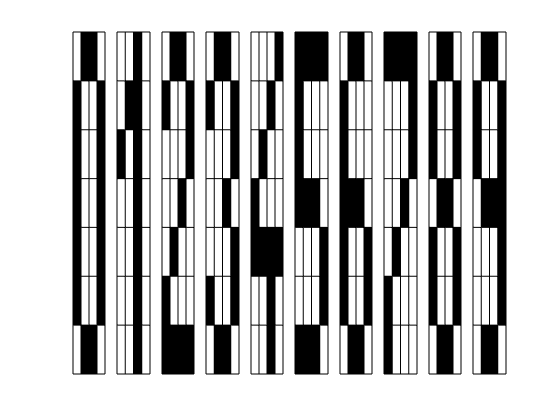

echo on
% Program na natrenovanie NS na rozpoznavanie cislic 0 az 9
% NS ma 28 vstupov - raster 4x7 - hodnota 0 az 1
% NS ma 10 vystupov - ake cislo je rozpoznane - hodnota 0 az 1

% vygenerovanie dat pre cislice 0 az 9
[dataX,dataY]=gennumbers(0:9);
dispznak(dataX,7,4);

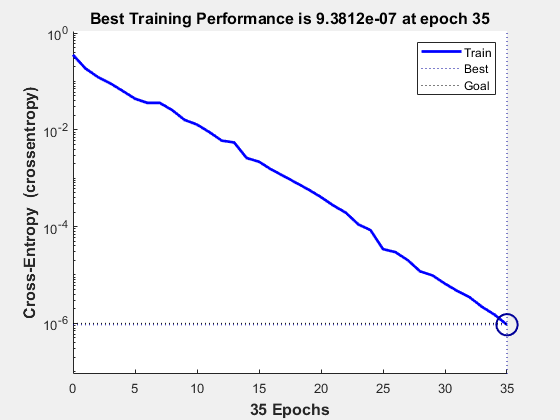

% zistenie rozmerov dat
[R,Q] = size(dataX);
[S2,Q] = size(dataY);

% vytvorenie struktury NS 
% 28 vstupov z rozsahom (0,1)
% 1 skryta vrstva s poctom neuronov 12 a funkciou 'tansig'
% 10 vystupov s funkciou 'softmax'
S1 = 12;
net = patternnet(S1);

% vsetky data pouzite na trenovanie
net.divideFcn='dividetrain';

% nastavenie parametrov trenovania epoch
net.trainParam.goal = 0.000001;     % error goal.
net.trainParam.show = 20;           % Frequency of progress displays (in epochs).
net.trainParam.epochs = 500;        % Maximum number of epochs to train.
net.trainParam.min_grad = 1e-10;    % ukoncovacia podmienka na min. gradient 

% trenovanie NS
[net,tr] = train(net,dataX,dataY);

% Zobrazenie chyby trenovania
figure, plotperform(tr)


% simulacia vystupu NS pre trenovacie data
% testovanie NS
outnetsim = sim(net,dataX)

outnetsim =     0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

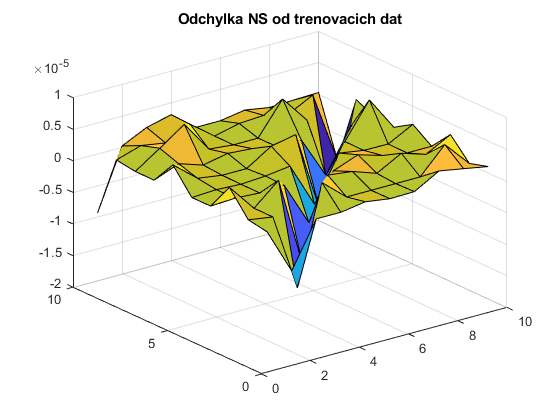


% chyba NS a dat
err=(outnetsim-dataY);
figure 
surf(err)
title('Odchylka NS od trenovacich dat')

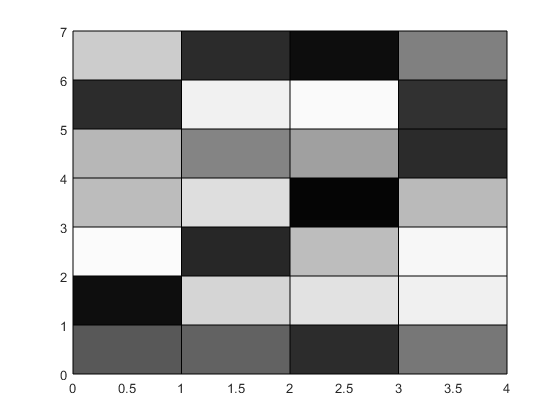


%------------------------------------------ Testovanie cisel 

% test 1
% cislo 2 so sumom 0.5			% noise interval <0; 0.5>
dataX=gennumbers(2,0.5);
dispznak(dataX,7,4);

cislo = sim(net,dataX)

cislo =     0.0000
    0.9999
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


cislo=round(cislo)'

cislo =      0     1     0     0     0     0     0     0     0     0


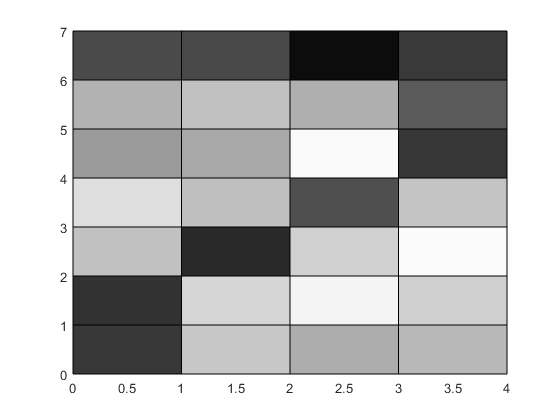


% test 2
dataX=gennumbers(7,0.4);
dispznak(dataX,7,4);

cislo = sim(net,dataX)

cislo =     0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9998
    0.0001
    0.0000
    0.0000


cislo=round(cislo)'

cislo =      0     0     0     0     0     0     1     0     0     0



echo off